# **Thermoeconomic Analysis Demo**

Use ThermoeconomicModel function to make the thermoeconomic analysis of a plant

### **Read and create the Thermoeconomic Model**

file='tgas_model.xml';
data=CheckDataModel(file);

INFO: cStatusLogger. Productive Structure is valid
INFO: cStatusLogger. Format Configuration is valid
INFO: cStatusLogger. Exergy values [Reference] are valid
INFO: cStatusLogger. Exergy values [TURB86] are valid
INFO: cStatusLogger. Exergy values [COMP86] are valid
INFO: cStatusLogger. Exergy values [PC78] are valid
INFO: cStatusLogger. Exergy values [T25] are valid
INFO: cStatusLogger. Exergy values [ECTR] are valid
INFO: cStatusLogger. Resources Cost sample [Base] is valid
INFO: cStatusLogger. Resources Cost sample [STACK] is valid
INFO: cStatusLogger. Waste definition is valid
INFO: cReadModelXML. Data Model tgas_model.xml is valid


if isValid(data)
    model=cThermoeconomicModel(data);
else
    return
end

#### Show productive structure info

res=model.productiveStructure;
printResults(res);

Flows Table

  Id  Key  From     To       Type     
---------------------------------------
   1  NG   ENV_R1   COMB_F1  RESOURCE 
   2  B2   COMP_P1  COMB_P1  INTERNAL 
   3  B3   COMB_P1  GTRB_F1  INTERNAL 
   4  B4   GTRB_F1  HRSG_F1  INTERNAL 
   5  B5   HRSG_F1  STCK_F1  INTERNAL 
   6  WC   GTRB_P1  COMP_F1  INTERNAL 
   7  WN   GTRB_P1  ENV_O1   OUTPUT   
   8  QV   HRSG_P1  ENV_O2   OUTPUT   
   9  QG   STCK_P1  ENV_W1   WASTE    


Streams Table

  Id  Key      Definition  Type     
-------------------------------------
   1  COMB_F1  NG          FUEL     
   2  COMB_P1  B3-B2       PRODUCT  
   3  COMP_F1  WC          FUEL     
   4  COMP_P1  B2          PRODUCT  
   5  GTRB_F1  B3-B4       FUEL     
   6  GTRB_P1  WC+WN       PRODUCT  
   7  HRSG_F1  B4-B5       FUEL     
   8  HRSG_P1  QV          PRODUCT  
   9  STCK_F1  B5          FUEL     
  10  STCK_P1  QG          PRODUCT  
  11  ENV_R1   NG          RESOURCE 
  12  ENV_O1   WN          OUTPUT   
  13  ENV_O2   QV    

#### Select a state and show its exergy values

States=convertCharsToStrings(model.getStateNames);
model.State=convertStringsToChars(States(2));
res=model.thermoeconomicState;
printResults(res);

Flows Exergy Table

  Id  Key  From     To            B(kW)
----------------------------------------
   1  NG   ENV_R1   COMB_F1     37491.0
   2  B2   COMP_P1  COMB_P1      9739.0
   3  B3   COMB_P1  GTRB_F1     33775.0
   4  B4   GTRB_F1  HRSG_F1     12143.0
   5  B5   HRSG_F1  STCK_F1      1073.0
   6  WC   GTRB_P1  COMP_F1     10468.0
   7  WN   GTRB_P1  ENV_O1      10000.0
   8  QV   HRSG_P1  ENV_O2       7168.0
   9  QG   STCK_P1  ENV_W1       1073.0


Streams Exergy Table

  Id  Key           E(kW)     ET(kW)
-------------------------------------
   1  COMB_F1     37491.0    37491.0
   2  COMB_P1     24036.0    33775.0
   3  COMP_F1     10468.0    10468.0
   4  COMP_P1      9739.0     9739.0
   5  GTRB_F1     21632.0    33775.0
   6  GTRB_P1     20468.0    20468.0
   7  HRSG_F1     11070.0    12143.0
   8  HRSG_P1      7168.0     7168.0
   9  STCK_F1      1073.0     1073.0
  10  STCK_P1      1073.0     1073.0
  11  ENV_R1      37491.0    37491.0
  12  ENV_O1      10000.0    1000

#### Show Diagram FP

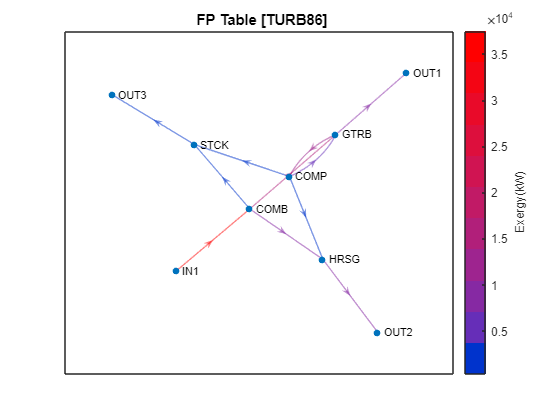

model.showDiagramFP;

#### Compute Direct and Generalized Exergy Cost

model.CostTables='DIRECT';
if model.isGeneralCost
    Samples=convertCharsToStrings(model.getResourceSamples);
    model.ResourceSample=convertStringsToChars(Samples(1));
end
res=model.thermoeconomicAnalysis;
printResults(res);

Process Exergy Cost

  Id  Key       P*(kW)    Pe*(kW)    Pr*(kW)     F*(kW)     R*(kW)
-------------------------------------------------------------------
   1  COMB     39181.8    37491.0     1690.8    37491.0     1690.8
   2  COMP     19279.4    18262.6     1016.8    19187.8       91.6
   3  GTRB     37517.7    35708.7     1809.0    37442.9       74.8
   4  HRSG     19161.1    18273.6      887.4    19161.1        0.0
   5  STCK      1857.3     1771.2       86.0     1857.3        0.0


Process Unit Exergy Cost

  Id  Key     kP*(J/J)  kPe*(J/J)  kPr*(J/J)   kF*(J/J)   kR*(J/J)     k(J/J)
------------------------------------------------------------------------------
   1  COMB      1.6301     1.5598     0.0703     1.0000     0.0703     1.5598
   2  COMP      1.9796     1.8752     0.1044     1.8330     0.0094     1.0749
   3  GTRB      1.8330     1.7446     0.0884     1.7309     0.0037     1.0569
   4  HRSG      2.6731     2.5493     0.1238     1.7309     0.0000     1.5444
   5  STCK  

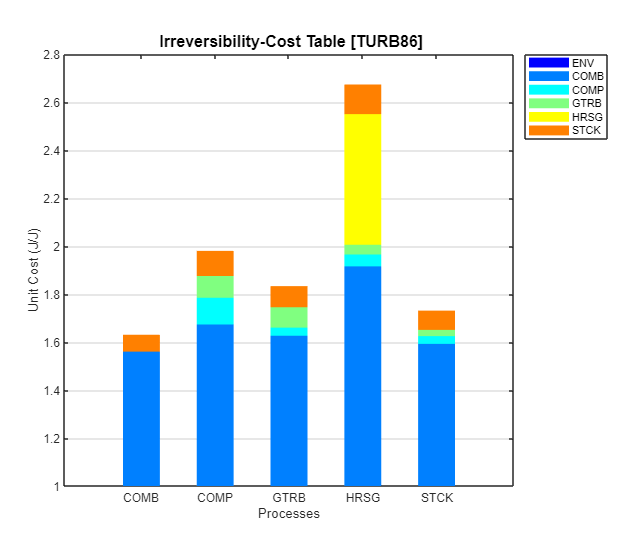

graphCost(res,cType.Graphs.PROCESS_COST);

#### Compare Reference and TURB86 states

model.DiagnosisMethod='WASTE_OUTPUT';
res=model.thermoeconomicDiagnosis;
model.fuelImpact;

Fuel Impact:   871.000 (kW)


printResults(res);

Diagnosis Sumary

  Id  Key       MF(kW)     DI(kW)    DPs(kW)    MF*(kW)    MR*(kW)   DPs*(kW)
------------------------------------------------------------------------------
   1  COMB       0.640    313.000      0.000      0.640      0.000      0.000
   2  COMP      -0.992     16.000      0.000     -1.730      0.000      0.000
   3  GTRB      92.181    106.000      0.000    152.297      0.000      0.000
   4  HRSG     198.300    198.300      0.000    327.408      0.000      0.000
   5  STCK       0.000      0.000    237.700      0.005      0.000    392.380
   6  ENV      290.129    633.300    237.700    478.620      0.000    392.380


 Malfunction Table (kW)

             COMB      COMP      GTRB      HRSG      STCK       DPs
--------------------------------------------------------------------
 COMB       0.000     0.000    65.184   140.908    -0.016     0.000
 COMP       0.000     0.000    26.997    57.392     0.016     0.000
 GTRB       0.000    -0.992     0.000     0.000     0.000

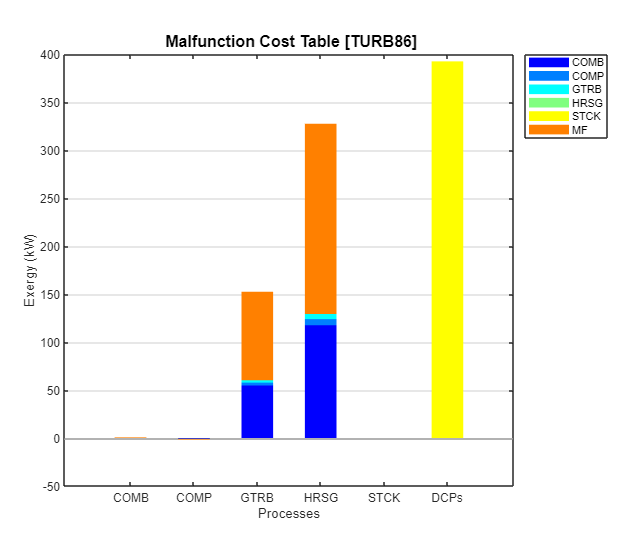

graphDiagnosis(res);

#### Save Result

Select result file using uiputfile and save as XLSX

saveResult=false;
if saveResult
    cd(path)
    file=uiputfile({'*.xlsx','XLSX Files'},'Select File','result.xlsx');
    log=saveResults(model,file);
    printLogger(log);
end